# Spatiotemporal stochastic volatility model -- Environmental risk modelling

In this live script, we demonstrate the usage of the dynamic stochastic volatility model using an empirical example from environmental science. As for applications in financial economics, the volatility of the process can be interpreted as risks (i.e., environmental risks in our case).

The full paper can be found on arXiv: [arXiv:2211.03178](https://arxiv.org/abs/2211.03178)

## Load packages, functions and Agrimonia dataset

We analyze the variation of fine dust concentrations of particles having a diameter less than 10 micrometers, PM10, in Lombardy, Northern Italy. Bounded by the Alps to the west, the region experiences reduced wind circulation, contributing to Lombardy being among the European regions with the lowest air quality. We use the daily PM10 concentrations from 1.1.2021 to 31.12.2021 from the official monitoring stations of the regional environmental authority, ARPA Lombardia. The data are open-source provided by the Agrimonia project: [https://zenodo.org/record/7956006](https://zenodo.org/record/7956006) (10.5281/zenodo.7956006).

clear all;

addpath(genpath("toolbox_may2021"))

load("AgrImOnIA_v3.0.0/AgrImOnIA_Dataset_v_3_0_0.mat")
agrimonia = AgrImOnIADataset;

## Reshaping of data, imputation and standardization

time = agrimonia.Time;
t = length(unique(time));
n = length(unique(agrimonia.IDStations));
locations = unique(agrimonia.IDStations);

coords = zeros(n, 3);

for i = 1:length(locations)
    idx = find(agrimonia.IDStations == locations(i));
    coords(i, 1) = i;
    coords(i, 2) = agrimonia.Latitude(idx(1));
    coords(i, 3) = agrimonia.Longitude(idx(1));
end

ymat = reshape(agrimonia.AQ_pm10, t, n)';

t2 = 2192;
t1 = 1827;
ymat = ymat(:, (t1+1):t2);
n2ind = find(mean(isnan(ymat), 2) ~= 1);
n2 = size(n2ind, 1);
ymat = ymat(n2ind, :);

ymat(isnan(ymat)) = nanmean(ymat, "all"); % na imputation
ymat(ymat == 0) = min(ymat(ymat > 0));

y = reshape(ymat, n2*(t2-t1), []); % reshape

covmat_blhmax = (reshape(agrimonia.WE_blh_layer_max, t, n)' - mean(agrimonia.WE_blh_layer_max, "all")) / sqrt(var(agrimonia.WE_blh_layer_max));
covmat_temp   = (reshape(agrimonia.WE_temp_2m, t, n)' - mean(agrimonia.WE_temp_2m, "all")) / sqrt(var(agrimonia.WE_temp_2m));
covmat_humid  = (reshape(agrimonia.WE_rh_mean, t, n)' - mean(agrimonia.WE_rh_mean, "all")) / sqrt(var(agrimonia.WE_rh_mean));
covmat_press  = (reshape(agrimonia.WE_surface_pressure, t, n)' - mean(agrimonia.WE_surface_pressure, "all")) / sqrt(var(agrimonia.WE_surface_pressure));

x = [ reshape(covmat_blhmax, n*t, []) reshape(covmat_temp, n*t, []) reshape(covmat_humid, n*t, []) reshape(covmat_press, n*t, [])]; % nT x p-dimensional matrix of regressors
xmat = reshape(x, n, t, 4);
xmat = xmat(n2ind, (t1+1):t2, :);
x = reshape(xmat, n2*(t2-t1), 4);

distmatfull = distance_miles(coords(:, 2), coords(:, 3));
coordsfull = coords;

coords = coordsfull(n2ind, :);
distmat = distance_miles(coords(:, 2), coords(:, 3));

## Descriptive plots

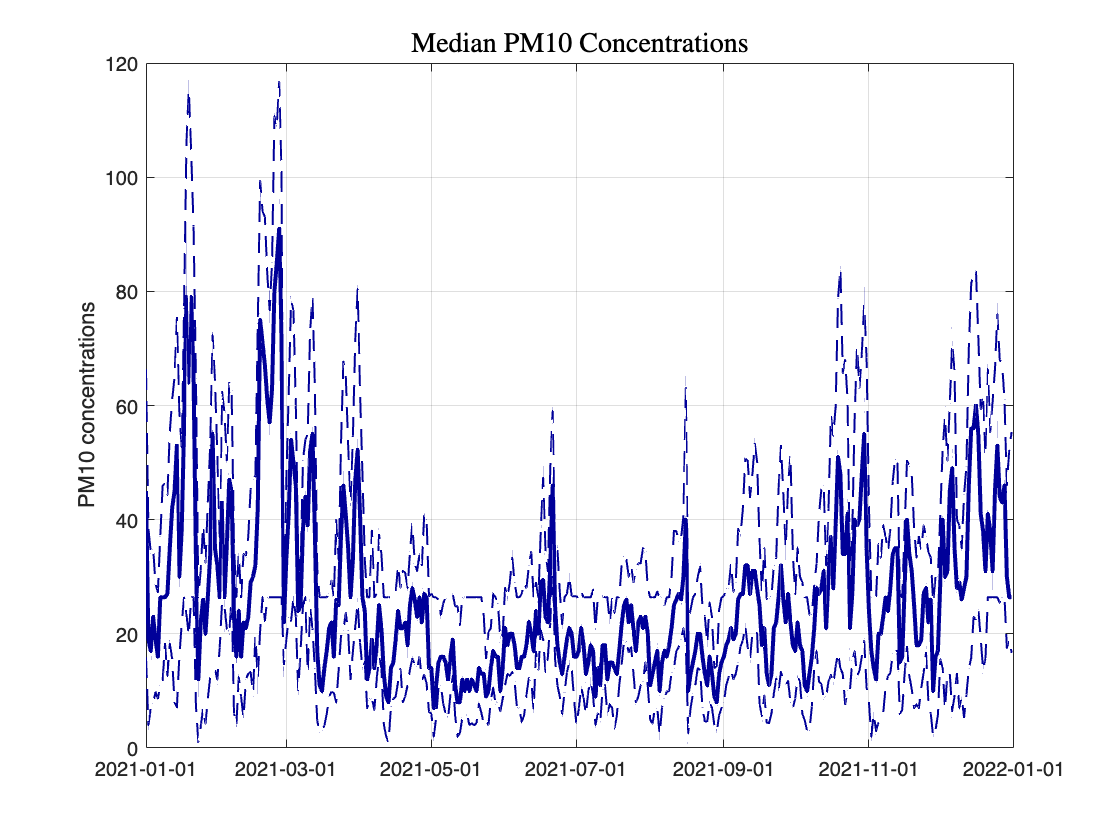

figure;
time_idx = string(unique(time));
ts1 = timeseries(median(ymat, 1), char(time_idx((t1+1):t2)));
ts2 = timeseries(quantile(ymat, 0.05, 1), char(time_idx((t1+1):t2)));
ts3 = timeseries(quantile(ymat, 0.95, 1), char(time_idx((t1+1):t2)));
ts1.Name = 'PM10 concentrations';
ts1.TimeInfo.Units = "days";
ts1.TimeInfo.StartDate = '2021-01-01';
ts1.TimeInfo.Format = 'yyyy-mm-dd';
ts2.TimeInfo.Units = "days";
ts2.TimeInfo.StartDate = '2021-01-01';
ts2.TimeInfo.Format = 'yyyy-mm-dd';
ts3.TimeInfo.Units = "days";
ts3.TimeInfo.StartDate = '2021-01-01';
ts3.TimeInfo.Format = 'yyyy-mm-dd';
p1 = plot(ts1, "-", 'LineWidth', 2, 'Color', [0,0,0.6]); hold on;
plot(ts2, "--", 'LineWidth', 1, 'Color', [0,0,0.6]); hold on;
plot(ts3, "--", 'LineWidth', 1, 'Color', [0,0,0.6]); hold on;
grid on;
hold off;
title('Median PM10 Concentrations','FontSize', 14, 'interpreter', 'latex'); 

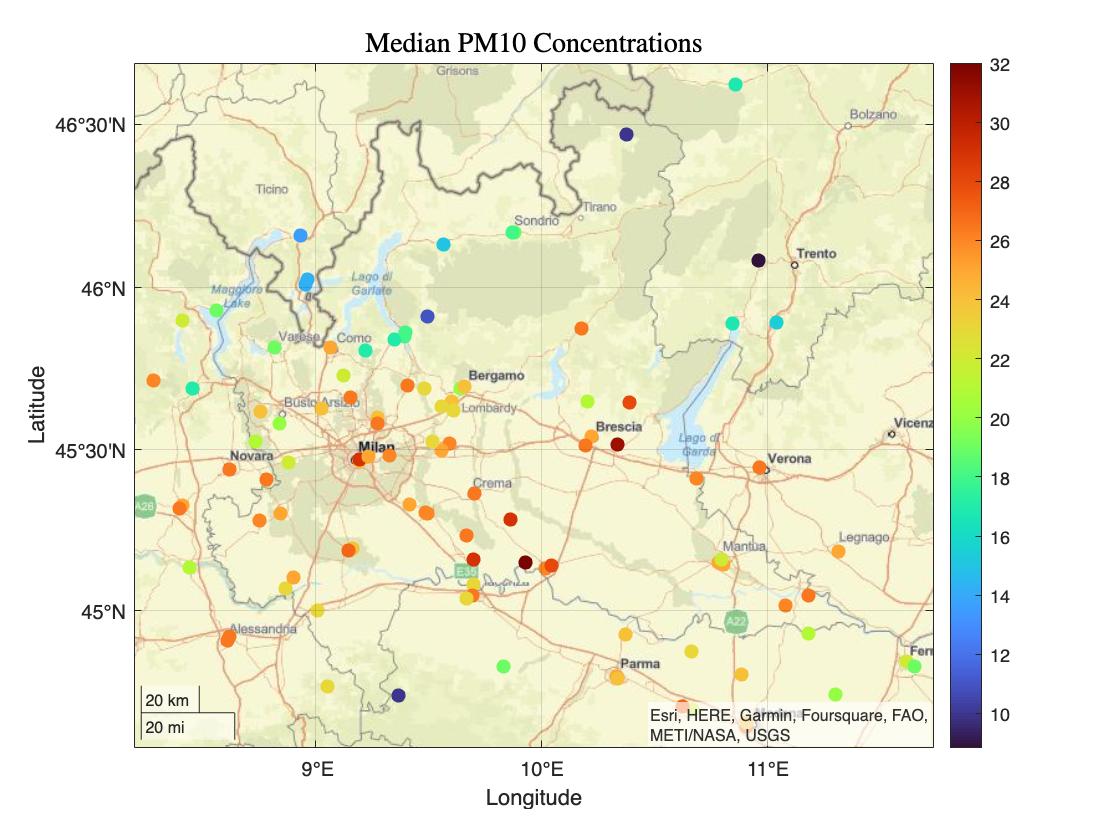


figure;
p2 = geoscatter(coords(:,2)', coords(:,3)', 50, median(ymat, 2), "filled");
geobasemap 'street';
colormap(turbo);
colorbar
hold off;
title('Median PM10 Concentrations','FontSize', 14, 'interpreter', 'latex'); 

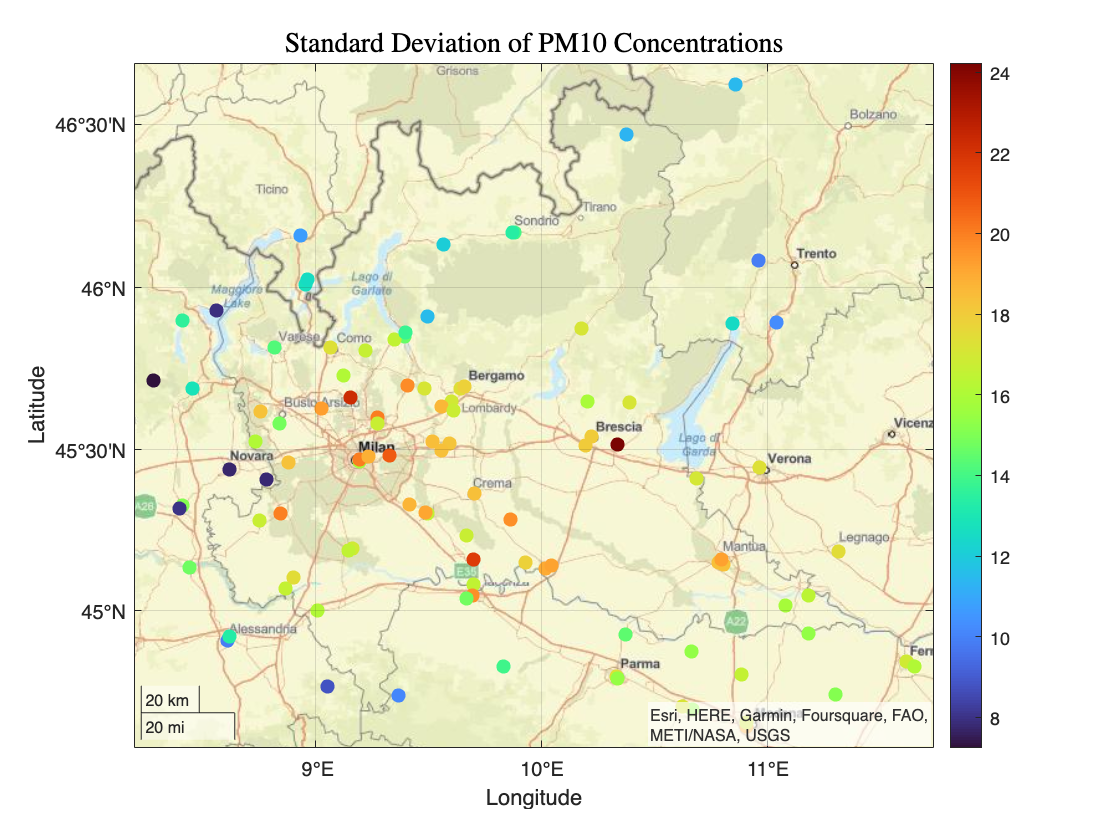


figure;
p3 = geoscatter(coords(:,2)', coords(:,3)', 50, std(ymat'), "filled");
geobasemap 'street';
colormap(turbo);
colorbar
hold off;
title('Standard Deviation of PM10 Concentrations','FontSize', 14, 'interpreter', 'latex'); 

## Selection of the spatial weight matrix

distance_cuts = [5:5:10, 10:2:35, 35:5:80];
rsq = zeros(2, max(size(distance_cuts))); % 2d array (invdist/binary, sequence of distances)

for cut_off = 1:max(size(distance_cuts))

    % binary case

    W = distmat < distance_cuts(cut_off) & distmat > 0; 
    n = size(W, 2);
    nterm = sum(W, 2);
    nterm = nterm + (nterm==0);
    W = W ./ nterm;

    info.model = 3; % 1 spatial fixed effects (x may not contain an intercept)
    results = sdm_panel_FE(y, x, W, t2-t1, info);
    rsq(1, cut_off) = results.sige;


    % inverse distance 

    W = distmat < distance_cuts(cut_off) & distmat > 0; 
    W = W .* (1 ./ distmat);
    n = size(W, 2);
    W(find(eye(size(W)))) = zeros(n,1);
    nterm = sum(W, 2);
    nterm = nterm + (nterm==0);
    W = W ./ nterm;

    info.model = 3; % 1 spatial fixed effects (x may not contain an intercept)
    results = sdm_panel_FE(y, x, W, t2-t1, info);
    rsq(2, cut_off) = results.sige;

end

weighting_scheme = plot(distance_cuts, rsq(1,:), "-o", col = "blue"); hold on
[M,IA] = min(rsq(1,:))

M = 57.1194

IA = 6

xline(distance_cuts(IA), "--", 'Color', "b")
plot(distance_cuts, rsq(2,:), "-o", 'Color', "r");
[M,IB] = min(rsq(2,:))

M = 52.9782

IB = 12

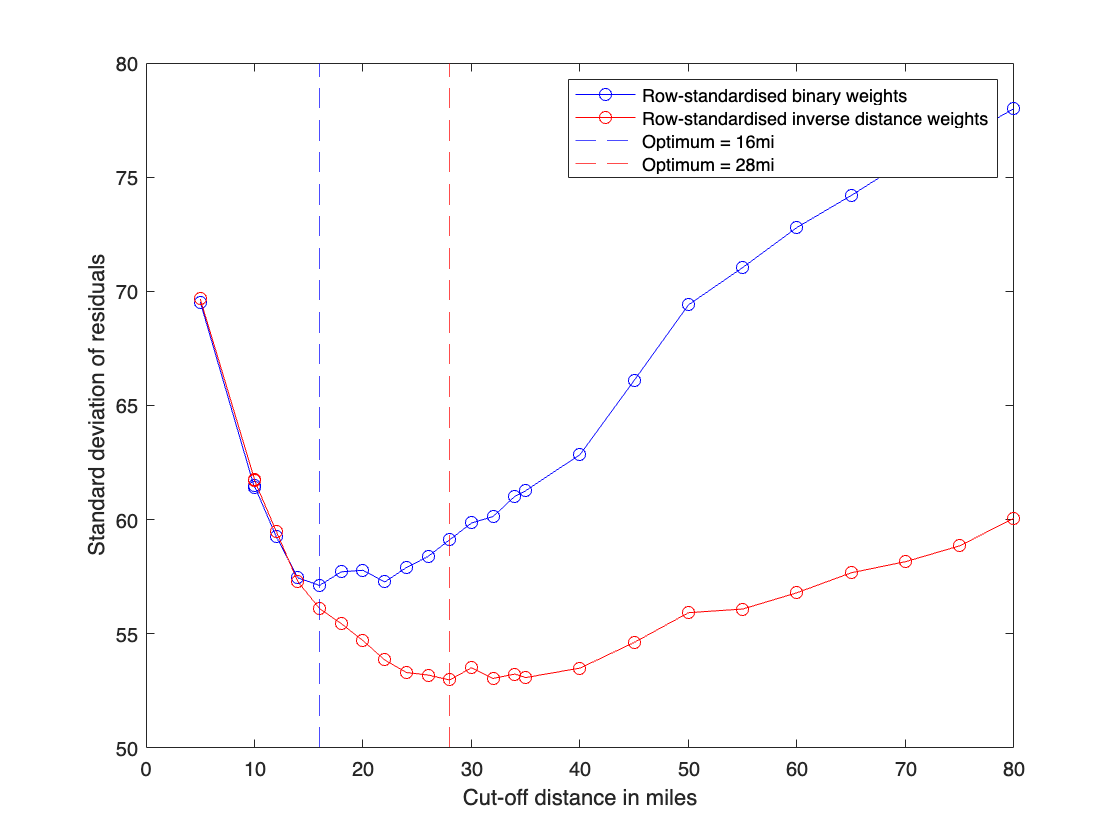

xline(distance_cuts(IB), "--", 'Color', "r")
legend("Row-standardised binary weights", "Optimum = " + string(distance_cuts(IA)) + "mi", "Row-standardised inverse distance weights", "Optimum = " + string(distance_cuts(IB)) + "mi")
xlabel("Cut-off distance in miles")
ylabel("Standard deviation of residuals")
hold off;


IB = 14; % note that the optimal cut-off distance depends on the numerical optimization in the estimation and many cut-off distance around the optimum lead to very similar results; 
% thus, the optimum may vary when repeatedly executing the code
W = distmat < distance_cuts(IB) & distmat > 0; 
nterm = sum(W, 2);
mean(nterm)

ans = 21.0485


W = W .* (1 ./ distmat);
[junk n] = size(W);
W(find(eye(size(W)))) = zeros(n,1);
nterm = sum(W, 2);
nterm = nterm + (nterm==0);
W = W ./ nterm;

1 - sum(W ~= 0, "all") / n^2

ans = 0.7956

## Mean model estimation


info.model = 3; % spatiotemporal fixed effects
results = sdm_panel_FE(y, x, W, t2-t1, info);

vnames = strvcat('PM10 concentrations', 'Boundary layer height (max)','Air temperature','Relative humidity','Air pressure');
prt_panel(results, vnames)

Homoscedastic model 
MaxLike SDM model with both region and time period fixed effects 
Dependent Variable = PM10 concentrations         
R-squared           =    0.8162   
corr-squared        =    0.0121   
sigma^2             =   53.2209 
Nobs,Nvar,#FE       =  37595,     8,   468  
log-likelihood     =       -130054.28 
# of iterations    =     18   
min and max rho     =   -1.0000,   1.0000 
total time in secs  =    0.3696 
time for lndet      =    0.0047 
Pace and Barry, 1999 MC lndet approximation used 
order for MC appr  =     50  
iter  for MC appr  =     30  
***************************************************************
Variable                           Coefficient  Asymptot t-stat    z-probability 
Boundary layer height (max)          -0.298873        -0.853461         0.393404 
Air temperature                      -6.778210        -5.690340         0.000000 
Relative humidity                     1.837893         6.725601         0.000000 
Air pressure                      

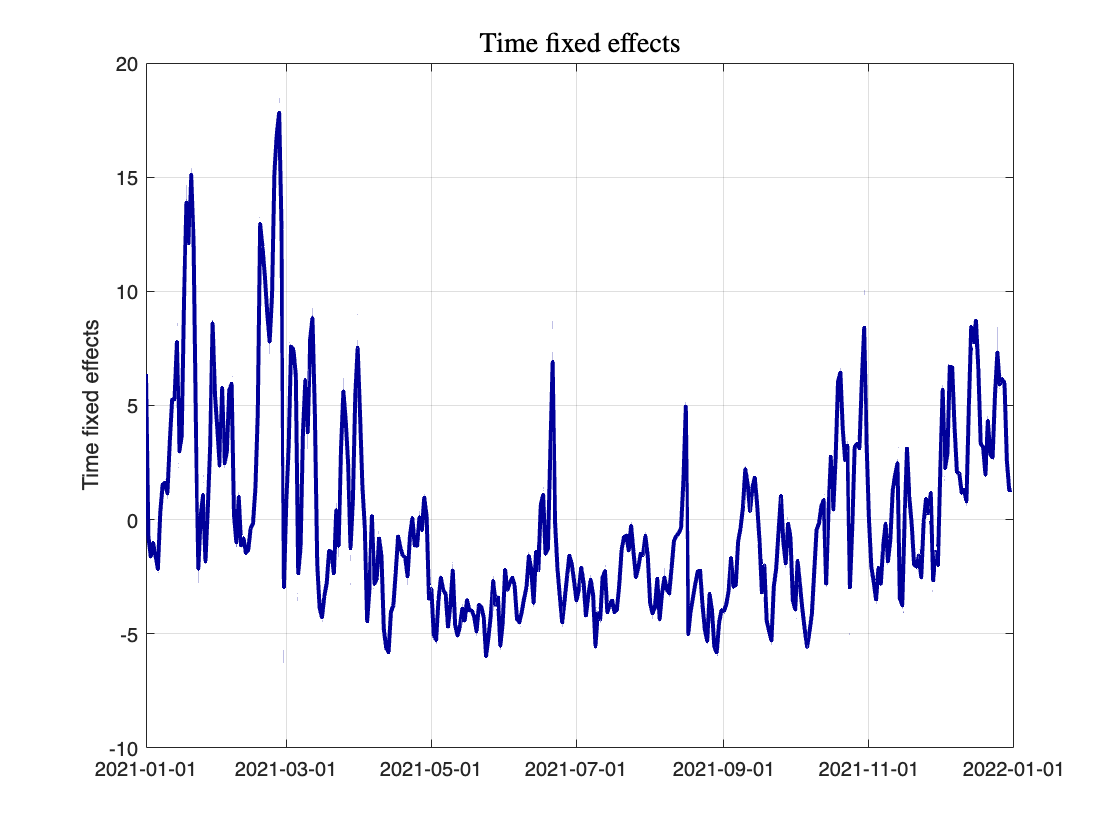


residuals = results.resid;
yhat = results.yhat;


time_idx = string(unique(time));
ts1 = timeseries(results.tfe, char(time_idx((t1+1):t2)));
ts1.Name = 'Time fixed effects';
ts1.TimeInfo.Units = "days";
ts1.TimeInfo.StartDate = '2021-01-01';
ts1.TimeInfo.Format = 'yyyy-mm-dd';
tfe = plot(ts1, "-", 'LineWidth', 2, 'Color', [0,0,0.6]); hold on;
grid on;
hold off;
title('Time fixed effects','FontSize', 14, 'interpreter', 'latex');

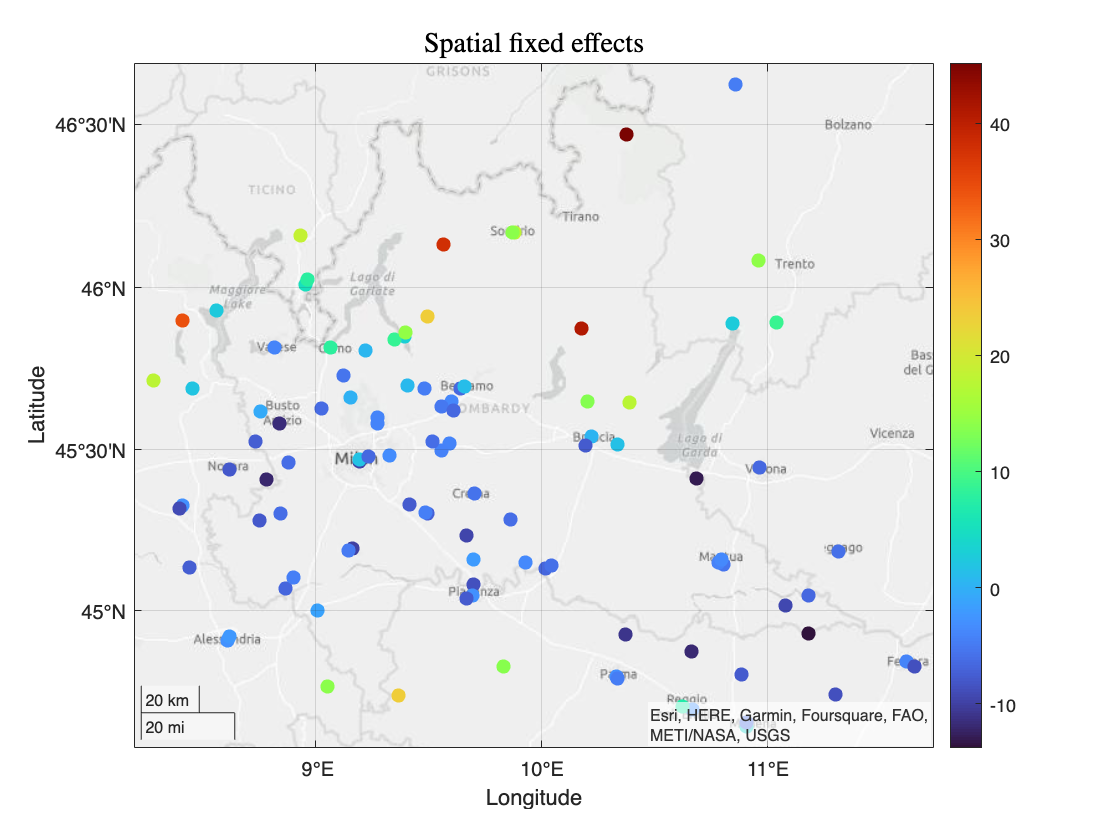


sfe = geoscatter(coords(:,2)', coords(:,3)', 50, results.sfe, "filled");hold on;
geobasemap 'streets-light';
colormap(turbo);
colorbar
hold off;
title('Spatial fixed effects','FontSize', 14, 'interpreter', 'latex');

## SVM model

The MCMC algorithm PSSV_10MH_packg is shown below in the last section of this file.

R1 = 2000;  % burnins
R2 = 4000;  % keepers

n = n2;
T = t2-t1;
N = n*T;

sigu2ini = 1.01;
rhoini = [0.01; 0.2; 0.01];
muhini = (-1) .* ones([n 1]);

a0 = 0.01; % shape
b0 = 0.01;  % scale
tau0 = 1;
mh0 = zeros([n 1]);
iVmh0 = 0.01.*speye(n);

hhini = log(var(residuals)).*ones([N 1]);


% Note that the estimation of the results needs a reasonable amount of
% memory (10.5GB) and time (approx 10 hours)

%tic;
%
%[Sdr, hdr, sigu2dr, muhdr, rhodr, count_rho] = PSSV_10MH_packg(residuals, W, R1, R2,...
%    a0, b0, mh0, iVmh0, tau0, hhini, rhoini, sigu2ini, muhini);
%
%toc


% median(mean(muhdr, 1))
% [ quantile(mean(muhdr, 1), 0.025) , quantile(mean(muhdr, 1), 0.975) ]

% median(rhodr(:,1))
% [ quantile(rhodr(:,1), 0.025) , quantile(rhodr(:,1), 0.975) ]
% median(rhodr(:,2))
% [ quantile(rhodr(:,2), 0.025) , quantile(rhodr(:,2), 0.975) ]
% median(rhodr(:,3))
% [ quantile(rhodr(:,3), 0.025) , quantile(rhodr(:,3), 0.975) ]

% median(mean(hdr, 1))
% [ quantile(mean(hdr, 1), 0.025) , quantile(mean(hdr, 1), 0.975) ]

% median(sigu2dr)
% [ quantile(sigu2dr, 0.025) , quantile(sigu2dr, 0.975) ]


## Analysis of the log-volatilities (maps)

load('hdraws_B.mat')


median(mean(hdr, 1))

ans = 3.1475

[ quantile(mean(hdr, 1), 0.025) , quantile(mean(hdr, 1), 0.975) ]

ans =     3.1307    3.1647



hdr_median_mat = zeros(n, T);

for t_id = 1:T;
    for n_id = 1:n;
        hdr_median_mat(n_id, t_id) = median(hdr((t_id - 1)*n + n_id, :));
    end
end

find(median(hdr_median_mat, 2) > 4.70) % 52

ans = 52

find(median(hdr_median_mat, 2) < 2) % 65

ans =     65
   103



find(datetime(char(time_idx((t1+1):t2))) == datetime('2021-06-26')) % 177

ans = 177

find(datetime(char(time_idx((t1+1):t2))) == datetime('2021-12-06')) % 340

ans = 340

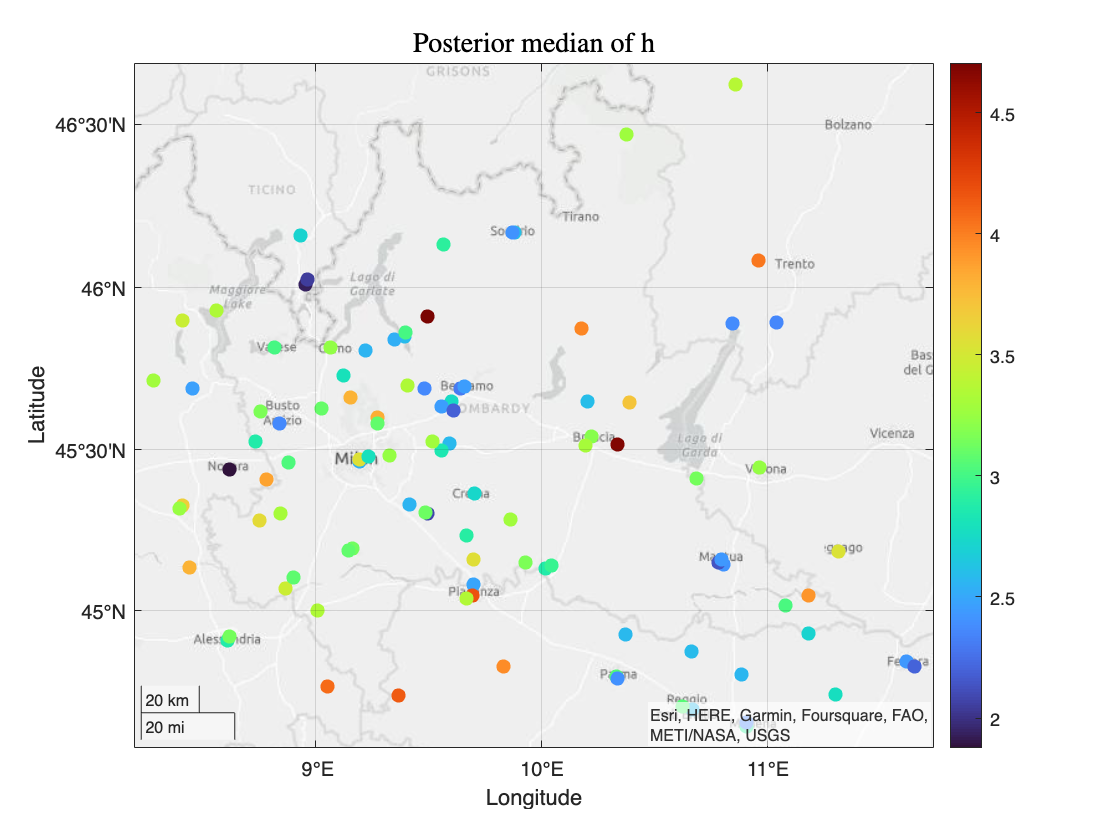


highlight_latitude1 = [coords(52,2)]; % Example highlighted latitudes
highlight_longitude1 = [coords(52,3)]; % Example highlighted longitudes
highlight_latitude2 = [coords(65,2)]; % Example highlighted latitudes
highlight_longitude2 = [coords(65,3)]; % Example highlighted longitudes

highlight_names1 = {'Station 52'}; % Example location names
highlight_names2 = {'Station 65'}; % Example location names

bottom = min(min(min(hdr_median_mat(:,177))),min(min(hdr_median_mat(:,340))));
top  = max(max(max(hdr_median_mat(:,177))),max(max(hdr_median_mat(:,340))));

figure;
p_median = geoscatter(coords(:,2)', coords(:,3)', 50, median(hdr_median_mat, 2), "filled");
geobasemap 'streets-light';
colormap(turbo);
colorbar
hold off;
title('Posterior median of h','FontSize', 14, 'interpreter', 'latex');

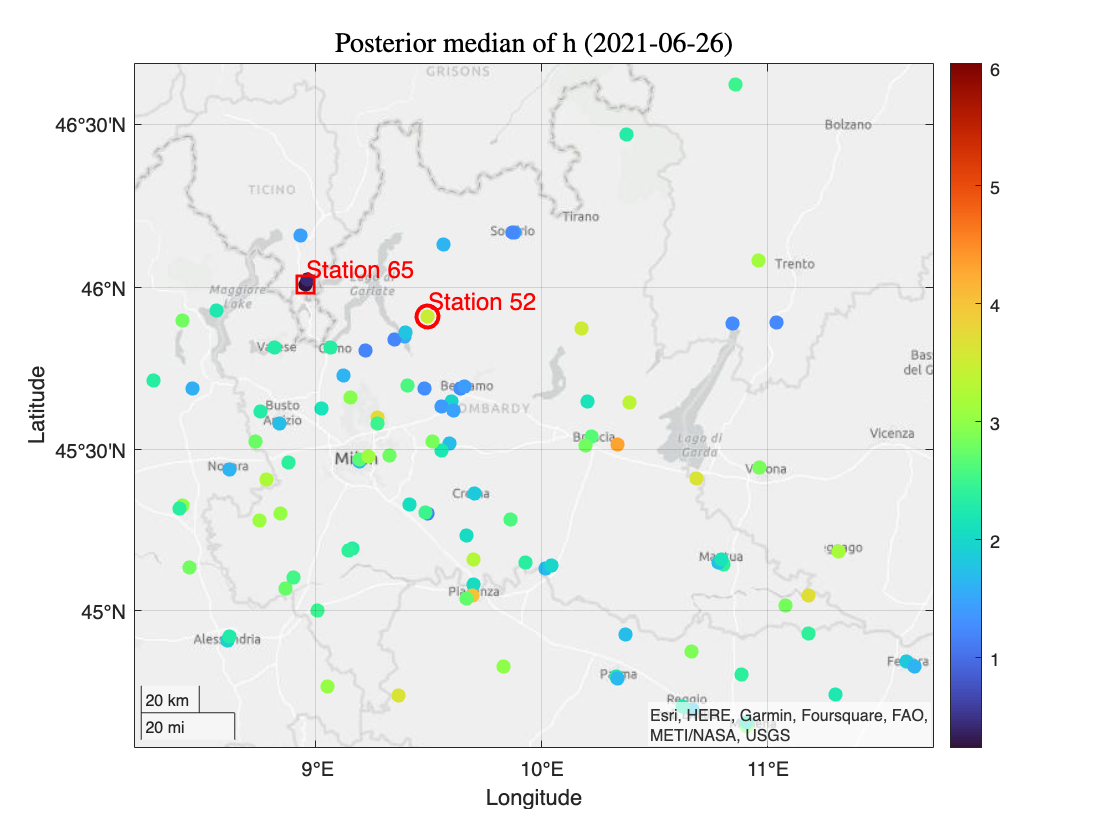

figure;
p_july = geoscatter(coords(:,2)', coords(:,3)', 50, hdr_median_mat(:,177), "filled");hold on;
caxis manual
caxis([bottom top]);
highlight = geoscatter(highlight_latitude1, highlight_longitude1, 120, 'r', 'o', 'LineWidth', 2); % Use a larger size and a red color
text(highlight_latitude1 + 0.05, highlight_longitude1, highlight_names1, 'Color', 'r', 'FontSize', 12);
highlight = geoscatter(highlight_latitude2, highlight_longitude2, 120, 'r', 's', 'LineWidth', 2); % Use a larger size and a red color
text(highlight_latitude2 + 0.05, highlight_longitude2, highlight_names2, 'Color', 'r', 'FontSize', 12);
geobasemap 'streets-light';
colormap(turbo);
colorbar
hold off;
title('Posterior median of h (2021-06-26)','FontSize', 14, 'interpreter', 'latex');

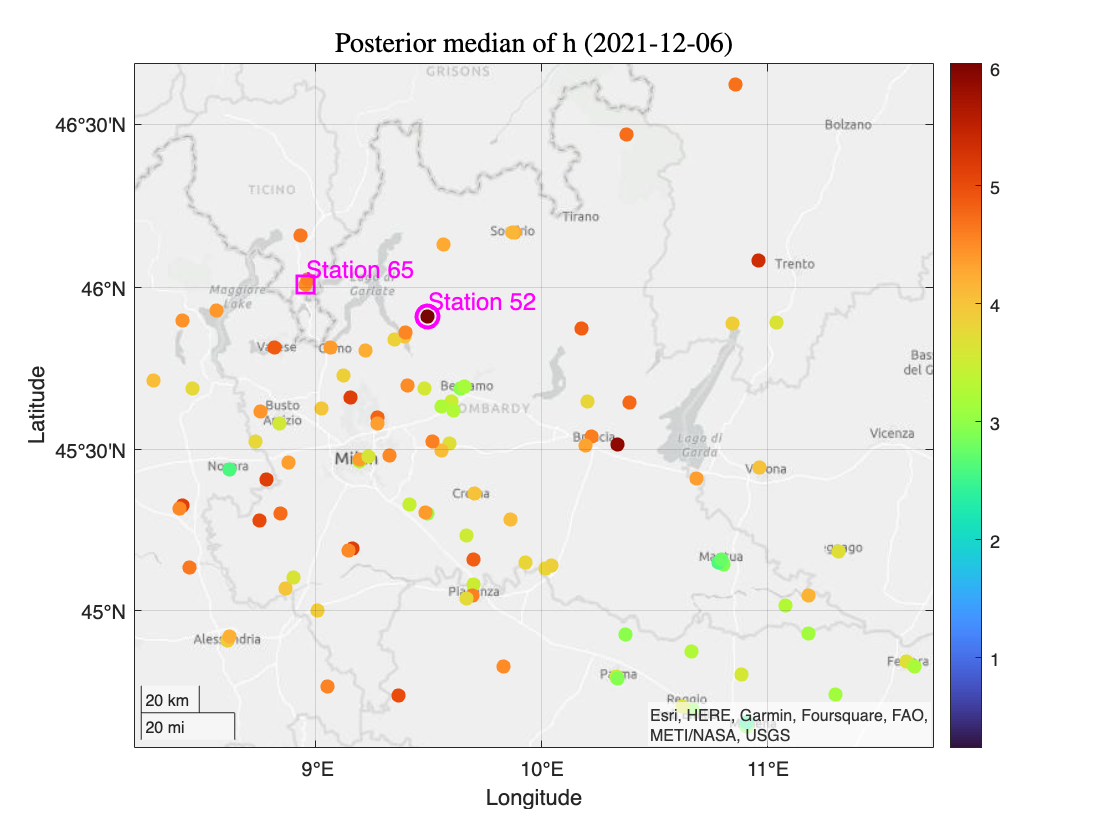

figure;
p_december = geoscatter(coords(:,2)', coords(:,3)', 50, hdr_median_mat(:,340), "filled");hold on;
caxis manual
caxis([bottom top]);
highlight = geoscatter(highlight_latitude1, highlight_longitude1, 120, 'm', 'o', 'LineWidth', 2); % Use a larger size and a red color
text(highlight_latitude1 + 0.05, highlight_longitude1, highlight_names1, 'Color', 'm', 'FontSize', 12);
highlight = geoscatter(highlight_latitude2, highlight_longitude2, 120, 'm', 's', 'LineWidth', 2); % Use a larger size and a red color
text(highlight_latitude2 + 0.05, highlight_longitude2, highlight_names2, 'Color', 'm', 'FontSize', 12);
geobasemap 'streets-light';
colormap(turbo);
colorbar
hold off;
title('Posterior median of h (2021-12-06)','FontSize', 14, 'interpreter', 'latex');

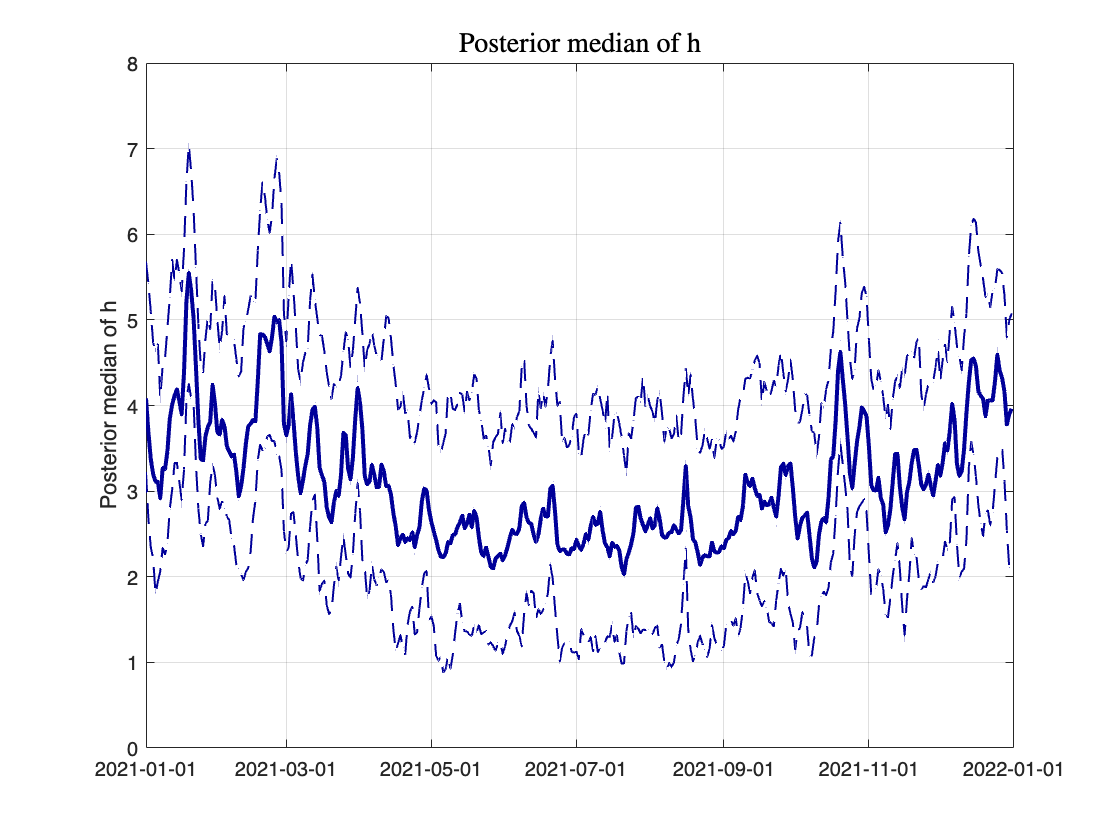

figure;
time_idx = string(unique(time));
ts1 = timeseries(median(hdr_median_mat, 1), char(time_idx((t1+1):t2)));
ts2 = timeseries(quantile(hdr_median_mat, 0.05, 1), char(time_idx((t1+1):t2)));
ts3 = timeseries(quantile(hdr_median_mat, 0.95, 1), char(time_idx((t1+1):t2)));
ts1.Name = 'Posterior median of h';
ts1.TimeInfo.Units = "days";
ts1.TimeInfo.StartDate = '2021-01-01';
ts1.TimeInfo.Format = 'yyyy-mm-dd';
ts2.TimeInfo.Units = "days";
ts2.TimeInfo.StartDate = '2021-01-01';
ts2.TimeInfo.Format = 'yyyy-mm-dd';
ts3.TimeInfo.Units = "days";
ts3.TimeInfo.StartDate = '2021-01-01';
ts3.TimeInfo.Format = 'yyyy-mm-dd';
p_median_h = plot(ts1, "-", 'LineWidth', 2, 'Color', [0,0,0.6]); hold on;
plot(ts2, "--", 'LineWidth', 1, 'Color', [0,0,0.6]); hold on;
plot(ts3, "--", 'LineWidth', 1, 'Color', [0,0,0.6]); hold on;
grid on;
hold off;
title('Posterior median of h','FontSize', 14, 'interpreter', 'latex');

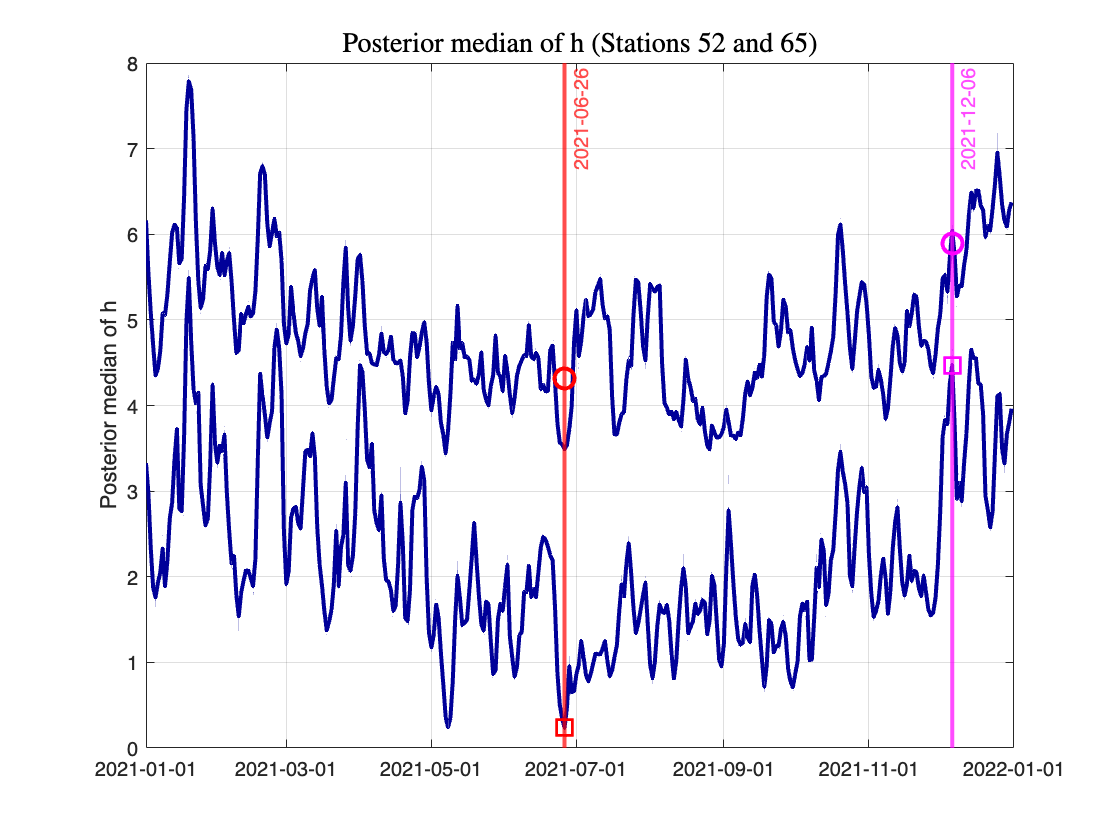


time_idx = string(unique(time));
ts1 = timeseries(hdr_median_mat(52,:), char(time_idx((t1+1):t2)));
ts2 = timeseries(hdr_median_mat(65,:), char(time_idx((t1+1):t2)));
ts1.Name = 'Posterior median of h';
ts1.TimeInfo.Units = "days";
ts2.TimeInfo.Units = "days";
ts1.TimeInfo.StartDate = '2021-01-01';
ts2.TimeInfo.StartDate = '2021-01-01';
ts1.TimeInfo.Format = 'yyyy-mm-dd';
ts2.TimeInfo.Format = 'yyyy-mm-dd';
p_time = plot(ts1, "-", 'LineWidth', 2, 'Color', [0,0,0.6]); hold on;
plot(ts2, "-", 'LineWidth', 2, 'Color', [0,0,0.6]); hold on;
xline(datetime('2021-06-26'),'r',{'2021-06-26'}, 'LineWidth', 2);
xline(datetime('2021-12-06'),'m',{'2021-12-06'}, 'LineWidth', 2);
scatter(datetime('2021-06-26'), hdr_median_mat(43,177), 100, 'r', "o", 'LineWidth', 2);
scatter(datetime('2021-06-26'), hdr_median_mat(65,177), 100, 'r', "s", 'LineWidth', 2);
scatter(datetime('2021-12-06'), hdr_median_mat(43,340), 100, 'm', "o", 'LineWidth', 2);
scatter(datetime('2021-12-06'), hdr_median_mat(65,340), 100, 'm', "s", 'LineWidth', 2);
grid on;
hold off;
title('Posterior median of h (Stations 52 and 65)','FontSize', 14, 'interpreter', 'latex');

## PSSV_10MH_packg

function [Sdr, hdr, sigu2dr, muhdr, psidr, count_psi] = PSSV_10MH_packg(y, ...
    W, R1, R2, a0, b0, mh0, iVmh0, tau, h, psi, sigu2, mu_h)
%--------------------------------------------------------------------------
% input:
% R1: burn-in's
% R2: held-in's
%--------------------------------------------------------------------------
%       # hyperparameters #
% a0  : shape parameter for the IG
% b0  : scale parameter for the IG
% muh0: mean of the prior for mu_h
% iVh0: precision of the prior for mu_h
% tau : uniform(-1/tau, 1/tau) (spectral radius of W)
%--------------------------------------------------------------------------
%        # initial values #
% h      : initial nT \times 1 vector of latent log-volatilities
% psi    : initial value of spatial auto-regressive parameters
% sigu2  : initial variance of u_i's
% mu_h   : initial n \times 1 vector of mean for h's
%--------------------------------------------------------------------------

N = length(y);
n = size(W, 1);
T = N/n;
pk = length(psi);
cc = 0.6/2.38^2;
R = R1 + R2;
count_psi = 0;

Sdr = zeros(N, R2);
hdr = zeros(N, R2);
sigu2dr = zeros(R2, 1);
muhdr = zeros(n, R2);
psidr = zeros(R2, pk);

% AMH initialization for psi
CovPsi = zeros(R+1, pk);
CovPsi(1, :) = psi';


% -- normal mixture components

pj = [.00609 .04775 .13057 .20674 .22715 .18842 .12047 .05591 .01575 .00115];
mj = [1.92677 1.34744 .73504 .02266 -.85173 -1.97278 -3.46788 -5.55246 -8.68384 -14.65000];
sigj2 = [.11265 .17788 .26768 .40611 .62699 .98583 1.57469 2.54498 4.16591 7.33342];
sigj = sqrt(sigj2);

ystar = log(y.^2);

for isim = 1:R   
    
    % -- sample mixture component indicators 
    % (from a 10-component discrete distribution)
    tmprd = rand([N 1]);
    q = repmat(pj, [N 1]).*normpdf(repmat(ystar, [1 10]),...
                                   repmat(h, [1 10]) + repmat(mj, [N 1]),...
                                   repmat(sigj, [N 1]));
    q = q./repmat(sum(q, 2), [1 10]);
    S = 10 - sum(repmat(tmprd, [1 10]) < cumsum(q, 2), 2) + 1;
    
    % -- sample h
    d_s = mj(S)';
    iSig_s = sparse(1:N, 1:N, 1./sigj2(S));
    krho = K_rho(psi, W, n);
    ki_rho = krho\speye(n);
    [tmp_i, tmp_m, tmp_l, tmp_o] = OMi(psi, W, ki_rho, n);
    tmp_a = blockdiag(tmp_i, kron(speye(T-2), tmp_m), tmp_l);
    tmp_b = kron(sparse(1:(T-1), 2:T, 1, T, T), tmp_o);
    Om = tmp_a + tmp_b + tmp_b';
    Omi = Om./sigu2;       % Omega^\star
    Bh = (iSig_s + Omi);
    Bmh = kron(ones([T 1]), mu_h);
    bhat = Bh\(Omi*Bmh + iSig_s*(ystar - d_s));
    h = bhat + chol(Bh, 'lower')'\randn([N 1]);  

    % -- sample mu_h
    s_Oi = ((tmp_i + (T-2).*tmp_m + tmp_l) + (T-1).*tmp_o + (T-1).*tmp_o')./sigu2; 
    Vmhat = (iVmh0 + s_Oi);
    Muhhat = Vmhat\(iVmh0*mh0 + sum(reshape(Omi*h, [n T]), 2));
    mu_h = Muhhat + chol(Vmhat,'lower')'\randn([n 1]);
    
    % -- sample sigu2
    hm = h - kron(ones([T 1]), mu_h);
    J_rho = kron(speye(T), (speye(n) - psi(1).*W)) +...
        kron(sparse(2:T,1:(T-1),1,T,T), -1.*(psi(2).*speye(n) + psi(3).*W));
    Pi_rho = blockdiag(ki_rho, speye(n*(T-1)));
    sigu2 = 1/gamrnd(a0 + N/2, 1/(b0 + ((hm'*(J_rho'*Pi_rho*J_rho)*hm)/2)));

    % -- sample psi via AMH step (rho in the paper)
    lpsi_i = llike_psi(psi, h, mu_h, sigu2, n, T, W);
    accept = 0;

    while (accept == 0) 
            if (isim <= 2*pk)
                psic = psi + sqrt(0.1^2/pk).*randn([pk 1]);
            else
                V_psi = cov(CovPsi(1:isim,:));
                % check pos-def ness
                [Vps, Dps] = eig(V_psi);
                dd = diag(Dps);
                for ij = 1:length(dd)
                    if dd(ij) <= 1e-10
                        dd(ij) = 1e-10;
                    end
                end
                V_psi = Vps*(diag(dd))*Vps';
                %
                uf = double(rand() < .95);
                psic = uf*(psi + chol(cc*(2.38^2/pk).*V_psi,'lower')*randn([pk 1])) +...
                    (1-uf)*(psi + sqrt(0.1^2/pk).*randn([pk 1]));
            end       
        % check the stability
        if (sum(abs(psic)) < (1/tau)) 
            accept = 1;
        end
    end
    %

    %
    lpsi_c = llike_psi(psic, h, mu_h, sigu2, n, T, W);
    if (lpsi_c - lpsi_i) > exp(1)
        pp = 1;
    else
        ratio = exp(lpsi_c - lpsi_i);
        pp = min(1, ratio);
    end
    if (rand() < pp)
        psi = psic;
        count_psi = count_psi + 1;
    end

    CovPsi(isim + 1, :) = psi';
    if (count_psi/isim < 0.4), cc = cc/1.05; end
    if (count_psi/isim > 0.6), cc = cc*1.05; end

    % -- store keepers
    if isim > R1
        Sdr(:, isim-R1) = S;
        hdr(:, isim-R1) = h;
        sigu2dr(isim-R1) = sigu2;
        muhdr(:, isim-R1) = mu_h;
        psidr(isim-R1, :) = psi';
    end
end
end
%


function Krho = K_rho(psi, W, n)
    rho1 = psi(1);
    rho2 = psi(2);
    rho3 = psi(3);
    Sin = (speye(n) - rho1.*W)\speye(n);
    An = rho2.*speye(n) + rho3.*W;
    tmp1 = An*Sin;
    tmp2 = tmp1*tmp1';
    for j = 2:15
        tmp1 = tmp1*(An*Sin);
        tmp2 = tmp2 + tmp1*tmp1';
    end
    Krho = tmp2;
end


function [tmp_i, tmp_m, tmp_l, tmp_o] = OMi(psi, W, ki_rho, n)
    rho1 = psi(1);
    rho2 = psi(2);
    rho3 = psi(3);
    Sn = (speye(n) - rho1.*W);
    An = rho2.*speye(n) + rho3.*W;
    tmp_i = (Sn'*ki_rho*Sn + An'*An);
    tmp_m = (Sn'*Sn + An'*An);
    tmp_l = (Sn'*Sn);
    tmp_o = -(An'*Sn);
end


function llk = llike_psi(PSI, h, mu_h, sigu2, n, T, W)
    Sn = (speye(n) - PSI(1).*W);
    krho = K_rho(PSI, W, n);
    ki_rho = krho\speye(n);
    [tmp_i, tmp_m, tmp_l, tmp_o] = OMi(PSI, W, ki_rho, n);
    tmp_a = blockdiag(tmp_i, kron(speye(T-2), tmp_m), tmp_l);
    tmp_b = kron(sparse(1:(T-1), 2:T, 1, T, T), tmp_o);
    Om = tmp_a + tmp_b + tmp_b';
    Omi = Om./sigu2;
    Bmh = kron(ones([T 1]), mu_h);
    llk = -(n*T)*log(sigu2)/2 + T*log(det(Sn)) - log(det(krho))/2 - ((h - Bmh)'*Omi*(h - Bmh))/2;  
end

